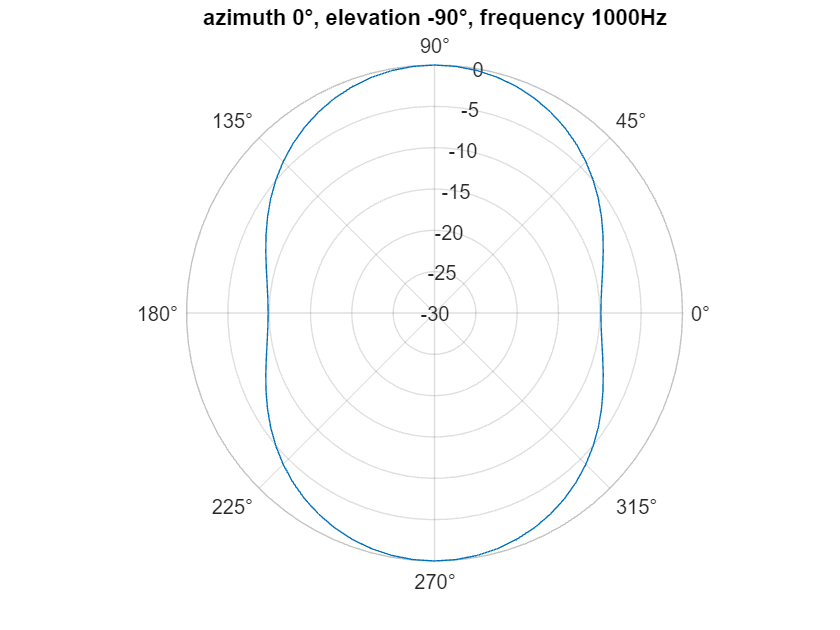

f_sound = 1000;

r = 0.1;
m_pos = [r 0 0; r/2 -sqrt(3)/2*r 0; -r/2 -sqrt(3)/2*r 0; -r 0 0; -r/2 sqrt(3)/2*r 0; r/2 sqrt(3)/2*r 0]';
%m_pos = [0 0 0; r 0 0; 0 -r 0; -r 0 0; 0 r 0; 2*r 0 0; 2*r/2 -sqrt(3)/2*2*r 0; -2*r/2 -sqrt(3)/2*2*r 0; -2*r 0 0; -2*r/2 sqrt(3)/2*2*r 0; 2*r/2 sqrt(3)/2*2*r 0; 3*r 0 0; 0 -3*r 0; -3*r 0 0; 0 3*r 0; 2*3*r 0 0; 2*3*r/2 -sqrt(3)/2*2*3*r 0; -2*3*r/2 -sqrt(3)/2*2*3*r 0; -2*3*r 0 0; -2*3*r/2 sqrt(3)/2*2*3*r 0; 2*3*r/2 sqrt(3)/2*2*3*r 0;]';
%m_pos = [0 0 -3*r; 0 0 -r; 0 0 r; 0 0 3*r]';
azimuth_deg = 0;
elevation_deg = -90;
azimuth = deg2rad(azimuth_deg);
elevation = deg2rad(elevation_deg);
s_pos = [cos(elevation)*cos(azimuth) cos(elevation)*sin(azimuth) sin(elevation)];

c = 343.3;
dasb_delay = s_pos*m_pos/c;

dasb = exp(-1j*2*pi*f_sound*dasb_delay);

sound_delay_angles = deg2rad(-180:5:180);
sound_delay_positions = [cos(sound_delay_angles')*cos(azimuth) cos(sound_delay_angles')*sin(azimuth) sin(sound_delay_angles')];
sound_delays = sound_delay_positions*m_pos/c;
simulations = dasb*exp(1j*2*pi*f_sound*sound_delays')/numel(m_pos(1,:));

threshold = -30;
for i = 1:numel(sound_delay_angles)
    if 20*log10(abs(simulations(i))) < threshold
        simulations(i) = 10^(threshold/20);
    end
end
polarplot(sound_delay_angles, 20*log10(abs(simulations)));
thetalim([0 360]);
thetaticks(0:45:315);
rlim([threshold 0]);
rticks(threshold:5:0);
title(sprintf("azimuth %d°, elevation %d°, frequency %dHz", azimuth_deg, elevation_deg, f_sound));